SaveFolder = '/media/DataMOBsRAIDN/PFC_InteroceptiveTuning/PhaseLocking';
cd(SaveFolder)
Period = 'All'

Period = 'All'

load(['DataPhaseLocking_PFC_BR_',Period,'.mat'])

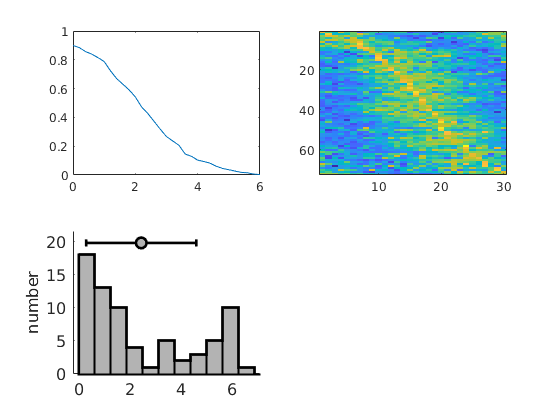

ans = 'Plot #1: mean=2.45, std=2.15, '

Method = 'WV';
clear Y mu Kappa pval R Z
i = 1;
for mm = 1:length(spikephase)
    for sp  = 1 :length(spikephase{mm}.(Method))
        phases = Data(spikephase{mm}.(Method){sp}.Nontransf);
        [Y(i,:),~] = hist(phases,30);
        [mu(i), Kappa(i), pval(i),R(i)] = CircularMean_SB(phases);
        Z(i) =  length(phases) * R(i)^2;
        SpikeNum(i) = length(phases);
        i = i+1;
    end
end

bins = [0:0.2:6];
for ii = 1:length(bins)
    DistCum(ii) = nanmean(log(Z)>bins(ii));
end
subplot(221)
plot(bins,DistCum)
subplot(222)
Ytemp = Y(GoodNeur,:);
[val,ind] = sort(mu(GoodNeur));
[~,ind] = max(Ytemp');
[~,ind] = sort(ind);
imagesc(zscore(Ytemp(ind,:)')')
subplot(223)
nhist(mu(GoodNeur))

Region = 'PFC'

Region = 'PFC'

TempBinsize = 0.2

TempBinsize = 0.2000

BinNumber = 6

BinNumber = 6

Parameter = 'BR'

Parameter = 'BR'


SaveFolder = '/media/DataMOBsRAIDN/PFC_InteroceptiveTuning/PFCTuningByVarAndPeriod';

load([SaveFolder,filesep,Parameter,'Tuning_',Period,'_',Region,'_',num2str(TempBinsize),'s_',num2str(BinNumber),'ParamBinNumber.mat'])

% Get all tuning curves
TrainTuning = [];
CVTuning = [];
AllP = [];
AllMI = [];
AllMI_Norm = [];
for sess = 1:length(TuningCurves)
    for neur = 1:length(TuningCurves{sess})
        TrainTuning = [TrainTuning;TuningCurves{sess}{neur}.HalfAn_STD];
        CVTuning = [CVTuning;TuningCurves{sess}{neur}.HalfCV];
        AllP = [AllP,TuningCurves{sess}{neur}.AnovaInfo];
        AllMI = [AllMI,MutInfo{sess}{neur}.MIPerSec];

        for i = 1:100, MIRand(i) = MutInfo_rand{sess}{neur}(i).MIPerSec; end
        AllMI_Norm = [AllMI_Norm,(MutInfo{sess}{neur}.MIPerSec - mean(MIRand))/std(MIRand)];

    end
end


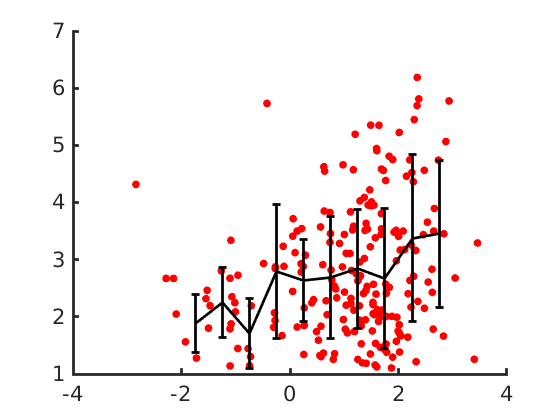

figure
GoodNeur = AllP<0.05 & pval<0.05;
AllMI_Norm(AllMI_Norm<0) = NaN;
MiToUse = log(AllMI_Norm(GoodNeur));
% ZToUse = Kappa(GoodNeur);
ZToUse = log(Z(GoodNeur));
SpikeNumToUse = log(SpikeNum(GoodNeur));

plot(MiToUse,ZToUse,'r.')
bins = [-2:0.5:3];
clear MnVal StdVal
for b = 1:length(bins)-1
    MnVal(b) = nanmean(ZToUse(MiToUse>bins(b) & MiToUse<bins(b+1) )) ;
    StdVal(b) = nanstd(ZToUse(MiToUse>bins(b) & MiToUse<bins(b+1) )) ;
end
hold on
errorbar(bins(1:end-1)+0.25,MnVal,StdVal,'color','k','linewidth',2)
makepretty

[R,P] = corrcoef(MiToUse,ZToUse,'rows','complete')

R =     1.0000    0.2255
    0.2255    1.0000


P =     1.0000    0.0009
    0.0009    1.0000




[R,P] = partialcorr(ZToUse',MiToUse',SpikeNumToUse','rows','complete')

R = 0.2021

P = 0.0030

% By frequency
FreqBins = [2,4,6,8,13];
i = 1;
clear Y_fq Kappa_fq pval_fq Z_fq Z_fq mu_fq
for mm = 1:length(spikephase)
    for sp  = 1 :length(spikephase{mm}.(Method))
        for ff = 1:length(FreqBins)-1
            freq = Data(spikefreq{mm}{sp});
            freqid = find(freq>FreqBins(ff) & freq<FreqBins(ff+1));
            phases = Data(spikephase{mm}.(Method){sp}.Nontransf);
            phases = phases(freqid);
            [Y_fq(i,ff,:), ~] = hist(phases,30);
            Y_fq(i,ff,:) = Y_fq(i,ff,:)/sum(Y_fq(i,ff,:));
            [mu_fq(i,ff), Kappa_fq(i,ff), pval_fq(i,ff),R_fq(i,ff)] = CircularMean_SB(phases);
            Z_fq(i,ff) =  length(phases) * R_fq(i,ff)^2;
        end
        i = i+1;
    end
end
disp('ok')

ok


GoodNeur = AllP<0.05 & pval<0.05;
clear pklocking
for neur = 1:size(Z_fq,1)
    [~,pklocking(neur)] = max(Z_fq(neur,:)- mean(Z_fq));
end


[~,ind] = max(TrainTuning');

[R,P] = corrcoef(pklocking(GoodNeur),ind(GoodNeur),'rows','complete')

R =     1.0000    0.0260
    0.0260    1.0000


P =     1.0000    0.6863
    0.6863    1.0000


neur = 1;
neur = neur+1;
clf
disp(num2str(Z_fq(neur,:)'))

0.84353
0.20728
0.26446
  2.463


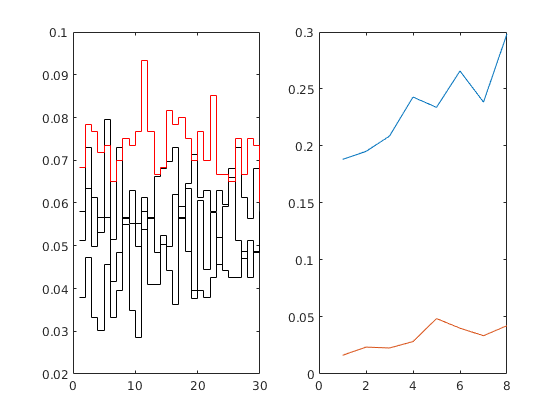

[~,ind] = max(Z_fq(neur,:) - mean(Z_fq));
PhaseLock = ((squeeze(Y_fq(neur,:,:))'));
subplot(121)
for ph = 1:4
    if ph ==ind
        stairs(PhaseLock(:,ph)+0.01*ph,'color','r')
    else
        stairs(PhaseLock(:,ph)+0.01*ph,'k')
    end
    hold on
end
subplot(122)
plot(TrainTuning(neur,:))
hold on
plot(CVTuning(neur,:))

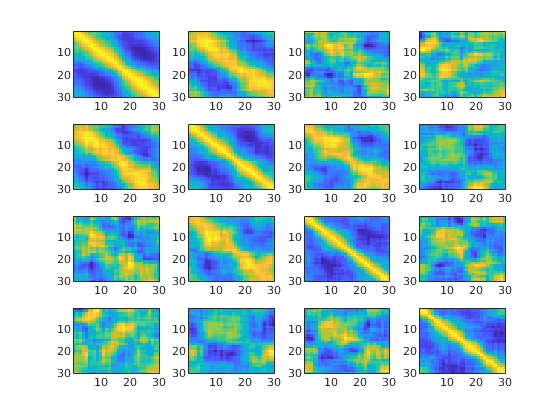

figure
for ff = 1:4
    for ff2 = 1:4
        Ytemp1 = smooth2a(squeeze(Y_fq(:,ff,:)),0,2);
        Ytemp2 = smooth2a(squeeze(Y_fq(:,ff2,:)),0,2);
        subplot(4,4,4*(ff-1)+ff2)
        imagesc(corr(Ytemp2,Ytemp1))

    end
end


for ff = 1:4
mu_sig{ff} = mu_fq(pval_fq(:,ff)<0.05,ff);
Z_sig{ff} = log(Z_fq(pval_fq(:,ff)<0.05,ff));
Kappa_sig{ff} = Kappa_fq(pval_fq(:,ff)<0.05,ff);  
end
figure
subplot(311)
nhist((mu_sig))

ans = 1×4 cell array
    {'Plot #1: mean=2.43, std=1.56, '}    {'Plot #2: mean=2.40, std=2.05, '}    {'Plot #3: mean=3.87, std=2.40, '}    {'Plot #4: mean=3.64, std=2.50, '}


subplot(312)
nhist((Z_sig))

ans = 1×4 cell array
    {'Plot #1: mean=2.65, std=1.24, '}    {'Plot #2: mean=2.36, std=0.95, '}    {'Plot #3: mean=2.36, std=0.99, '}    {'Plot #4: mean=2.14, std=0.82, '}


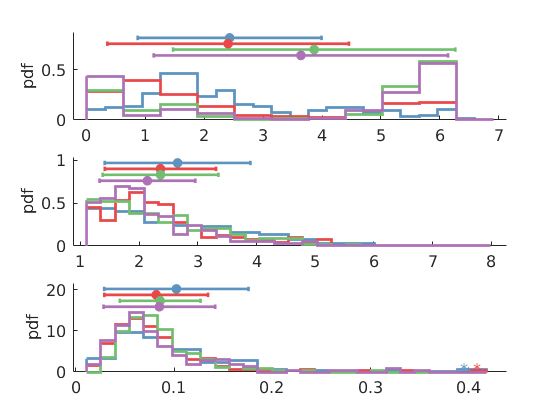

ans = 1×4 cell array
    {'Plot #1: mean=0.10, std=0.07, 3 points counted in the rightmost bin are greater than 0.39 , '}    {'Plot #2: mean=0.08, std=0.05, 1 points counted in the rightmost bin are greater than 0.40 , '}    {'Plot #3: mean=0.09, std=0.04, '}    {'Plot #4: mean=0.09, std=0.06, '}


subplot(313)
nhist((Kappa_sig))

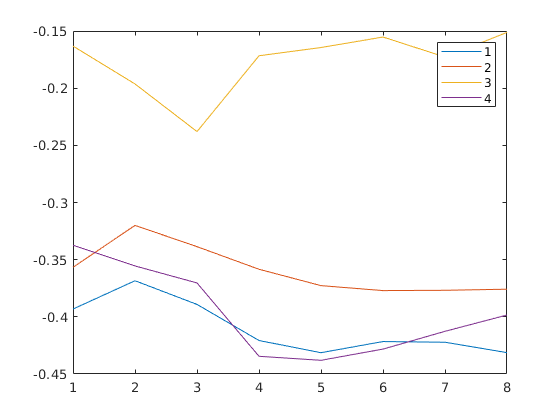


figure
TrainTuningZ = zscore(TrainTuning')';
for ff = 1:4
GoodNeur = pval_fq(:,ff)<0.05;
BadFF= find(~ismember(1:4,ff));
for fnot = 1:length(BadFF)
    BadNeur(:,fnot) = pval_fq(:,BadFF(fnot))<0.05;
end
GoodNeur = GoodNeur & sum(BadNeur')'==0;
plot(nanmean(TrainTuningZ(GoodNeur,:)) - nanmean(TrainTuningZ(:,:)));
hold on
end
legend('1','2','3','4')